# Modeling the three stages in HIV infection.

Esteban A. Hernandez-Vargas, Richard H. Middleton. 2012.

Las células huésped objetivo del VIH son principalmente las CD4+T, macrófagos  y las células denditricas. Los marcadores principales para la progresión de la infección de VIH son el conteo de CD4+T y los niveles de carga viral plasmática. En un paciente típico se tienen tres principales etapas: Iniciamos con una infección aguda, continuamos con un periodo asintomático largo y finalmente un incremento explosivo en la carga viral con un colapso en el conteo de las células CD4+T,  es ahí cuando el SIDA aparece junto a enfermedades oportunistas.

A continuación se expone un modelo para representar las tres etapas antes mencionadas, por medio de un sistema de ecuaciones diferenciales ordinarias acopladas, en donde se consideran cinco variables de interés:  Conteo de celulas CD4+T sanas por $mm^3
$ ($T
$), células CD4+T infectadas por $mm^3
$ ($T^*
$), macrófagos sanos por por $mm^3
$ ($M

$), macrófagos infectados por $mm^3
$($M^*
$) y las copias del virus por ml ($V
$).

- 
$$
\dot{T} = s_T+\frac{\rho_T V}{C_T+V}T-k_TTV-\delta_TT
$$


- 
$$\dot{T}^{*} = k_TTV-\delta_{T^*}T^*$$
 

- 
$$\dot{M} = s_M+\frac{\rho_MV}{C_M+V}M-k_MMV-\delta_MM$$


- 
$$\dot{M}^* = k_MMV-\delta_{M^*}M^*$$


- 
$$\dot{V} = p_TT^*+p_MM^*-\delta_VV$$


La ecuación 1 habla sobre el cambio a tráves del tiempo que sufre la cantidad de células CD4+T, existe un término fuente $s_T
$ el cual representa la proporción de generación de nuevas células CD4+T, el siguiente término es un crecimiento logístico para las células CD4+T que se encuentra limitado por la carga viral; ahora retiramos del total las celulas que han sido infectadas del virus con una proporción $k_T$ y aquellas que murieron de forma natural $\delta_T
$.

La ecuación 2 dice la dinámica de las células CD4+T infectadas, se van sumando las nuevas células infectadas a razón de $k_T
$ menos aquellas que mueren $\delta_{T^*}$.

La ecuación 3 es la evolución de los macrófagos, contando con un término fuente $s_M$, de nuevo un término de crecimiento logístico menos aquellos macrófagos que han sido infectados con tasa $k_M$ y los que mueren de forma natural $\delta_M$.

La ecuación 4 expresa la evolución de los macrófagos infectados, a partir de una infección con tasa $k_M
$ menos los que perecen a tasa $\delta_{M^*}$.

Finalmente, la ecuación 5 muestra el cambio de la carga viral, en donde existen dos términos que agregan nuevas copias del virus que se produjeron en el cuerpo a tasa $p_T$ para las células CD4+T infectadas y tasa $p_M$ en relación a los macrófagos infectados,

también, una cantidad de virus perece en el proceso a una proporción $\delta_V$.

La forma en la que codifica son las siguientes:

Ahora procederemos con la construcción de las gráficas de la ecuación diferencial para visualizar la dinámica.

Tmax=10*365; % Días equivalenes a diez años
[t,y] = ode45(@VassilisModel, [0,Tmax],[1000 0 150 0 1e-3]); %Funcion ODE
T = y(:,1); %CD4 Saludables
Ti = y(:,2); %CD4 infectados
M = y(:,3); %Macrofagos
Mi = y(:,4); % Macrofagos infectados
V= y(:,5); % Virus
%Greenough
%------------------------------------------------------------------------
%t1=[ 365,  730, 1095, 1460,  2200, 2560, 2900];
%T1=[ 620,  580,  500,  430,   305,  280,  120];
t1=[ 365,  730, 1095, 1460, 1825,  2190, 2555, 2920,3285, 3650];
T1 = [620,540,400,330,305,280,240,190,100,50];
%DATA of Fauci
%-------------------------------------------------------------------------
% %Progressor
% t3=[ 65,   730, 1095, 1460, 1825, 2200, 2600, 3500;];
% T3=[  560,   470,  380,  300,  280,  242, 180,  160;];
%--------------------------------------------------------------------------
t3=[  1  , 21 ,  42,   84,  365, 730, 1095, 1460, 1825, 2190, 2555, 2920,3285, 3650];
T3=[ 1000, 900, 500,  680,  600, 530,  500,  450,  430,  350,  280, 250,  50,   10];

La siguiente gráfica es la el conteo de células CD4+T sanas e infectadas, pues ambas son el total del mismo tipo de células. Notamos que en una infección temprana existe una gran pérdida que representa la etapa aguda, en donde el paciente infectado puede presentar síntomas como fiebre, faringitis, dolor de cabeza y  sarpullido. Porteriormente hay un período en donde los niveles son aceptables, el indicador para el diagnóstico de SIDA es un conteo por debajo de las 200 células por $mm^3$.

figure(1);
sim_V = plot(t/365, T+Ti, 'LineWidth',2);
axis([0, Tmax/365,1,1000]);
xlabel('Time(years)');
ylabel('T+T* (cells/mm^3)', 'fontsize', 10.0);
hold on 
V_pony1 = plot(t1/365, T1, 'ks');
hold on
V_pony5 = plot(t3/365, T3, 'kd');
hold on

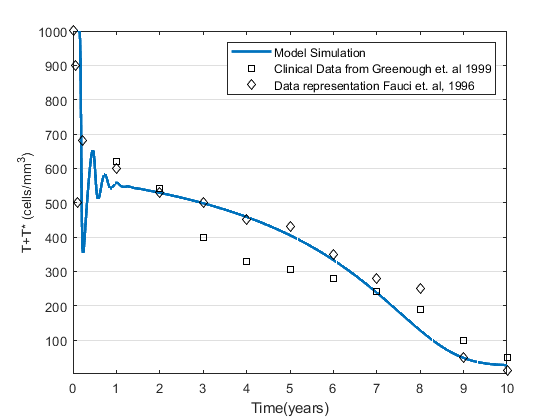

%Detalles para las leyendas
hVGroup = hggroup;
hvpony1 = hggroup;
hvpony5 = hggroup;
set(sim_V, 'Parent', hVGroup);
set(V_pony1, 'Parent', hvpony1);
set(V_pony5, 'Parent', hvpony5);
%Incluimos hggroups en la leyenda
set(get(get(hVGroup, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle','on'); 
set(get(get(hvpony1, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle','on');
set(get(get(hvpony5, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle','on');
legend('Model Simulation', 'Clinical Data from Greenough et. al 1999', ...
    'Data representation Fauci et. al, 1996');

set(gca,'XGrid','off','YGrid','on')

La siguiente gráfica corresponde a la cantidad de copias del virus por milímetro. Temporalmente se adecua con las células CD4+T, pues en el inicio hay explosión en la cantidad de copias, así como suben también bajan entrando en un período de constancia hasta

que después de años se vuelve a tener un crecimiento que corresponde con el diagnóstico del SIDA.

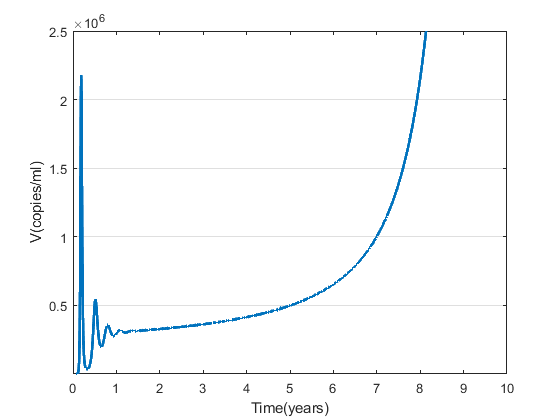

figure(2);
plot(t/365, V/0.001, 'LineWidth', 2);
ylabel('V(copies/ml)');
xlabel('Time(years)');
axis([0, Tmax/365,1,2500000]);

set(gca,'XGrid','off','YGrid','on')

La siguiente gráfica es la representación de células CD4+T infectadas, notemos que al inicio hay una gran infección entre este conjunto pero después se mantiene constante a pesar de que el conteo de carga viral aumente como se vio en la gráfica anterior, esto nos habla que los macrófagos infectados tienen una influencia mucho más grande que los CD4+T.

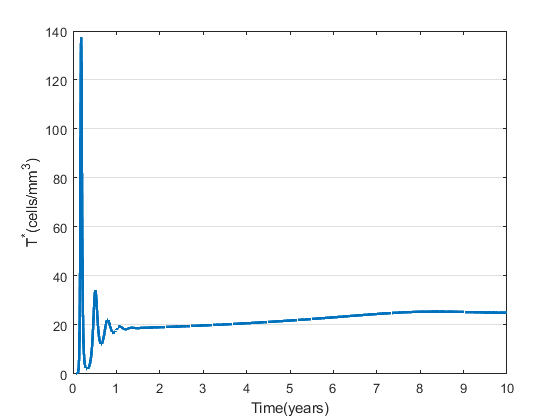

figure(3);
plot(t/365, Ti, 'LineWidth',2);
ylabel('T^*(cells/mm^3)');
xlabel('Time(years)');

set(gca,'XGrid','off','YGrid','on')

Siguiendo el análisis de las ecuaciones respecto al tiempo, continuamos con los macrógados sanos, que tienen un crecimiento exponencial en su tasa de reproducción hasta que al final decaen de una forma muy rápida, es decir, en un año, entre el noveno y décimo pierde aproximadamente 2000 células por $mm^3$. Esto se relaciona fuertemente con la siguiente gráfica.

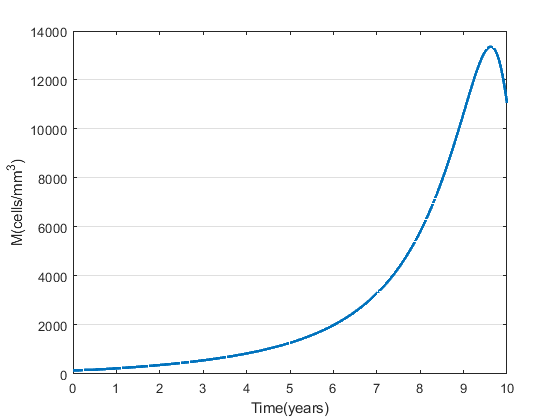

figure(4);
plot(t/365, M, 'LineWidth',2);
ylabel('M(cells/mm^3)');
xlabel('Time(years)');

set(gca,'XGrid','off','YGrid','on')

Por último se tiene el conteo de macrófagos infectados, que no tienen un crecimiento en la etapa de infecccióna aguda y la etapa asintomática, no obstante, en los últimos años hay un crecimiento exponencial en el conteo de macrófagos infectados, esto suma con la carga viral, pues nos indica que en la etapa tardía ya no importan tanto los CD4+T como se vio, si no que los verdaderos agentes de impacto son los macrófagos.

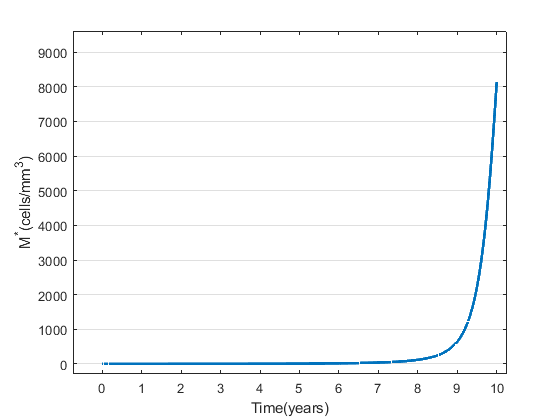

figure(5);
plot(t/365, Mi, 'LineWidth',2);
ylabel('M^*(cells/mm^3)');
xlabel('Time(years)');

xlim([-0.74 10.26])
ylim([-289 9611])
set(gca,'XGrid','off','YGrid','on')

Función de la ecuación diferencial.

function dy = VassilisModel(tiempo, y)
    %Parametros
    s1 = 10; %Fuente de CD4
    s2 = 0.15; %Fuente de Macrofagos
    K2 = 4.5714e-005; %Ratio de infeccion CD4
    K4 = 4.3333E-008; %Ratio infeccion Macrofagos
    K5 = 38; %5.37e-1; %Cantidad produccion CD4 infectados
    K6 = 35; %2.85e-1; %Cantidad produccion Macrofagos infectados
    %Proporción de muerte 
    d1 = 0.01; %Muerte Natural CD4
    d2 = 0.4; %Muerte Natural Macrofagos
    d3 = 0.001; % Muerte Natural CD4 infectados
    d4 = 0.001; %Muerte natural Macrofagos infectados
    d5 = 2.4; %Muerte de los virus
    pT = 0.01*(y(1)*y(5))/(y(5)+300); %Factor Logistico crecimiento CD4
    pM = 0.003*(y(3)*y(5))/(y(5)+220); %Factor Logistico Crecimiento Macrofagos
    % Modelo de Vassilis
    dy = zeros(5,1); %Creacion vector de variables
    dy(1) = s1-d1*y(1)-K2*y(5)*y(1)+pT; %Dinamica CD4
    dy(2) = K2*y(5)*y(1)-d2*y(2); %Dinamica CD4 Infectado
    dy(3) = s2-K4*y(3)*y(5)-d3*y(3)+pM; %Dinamica Macrofagos 
    dy(4) = K4*y(5)*y(3)-d4*y(4); %Dinamica Macrofagos infectados
    dy(5) = K5*y(2)+K6*y(4)-d5*y(5); %Dinamica Carga Viral
end